# Tryout transformer sequence prediction

Idea taken from here:

https://ch.mathworks.com/matlabcentral/fileexchange/161016-transformer-networks-for-time-series-prediction/

% INIT
% Init Transformers

logger('Starting creating of transformer netowrk and test it', 'INFO');

[2025-02-16 00:26:21] [INFO] [acuna@PC175] Starting creating of transformer netowrk and test it


%{
 animal_list = {'326', '327', '328', '330', '332_training', '332', '334', '335', '336'};
 
%}

clc, clear

GC = general_configs(); % load general configurations

%% Load Data
logger('Loading data', 'INFO');

[2025-02-16 00:26:21] [INFO] [acuna@PC175] Loading data


% Load analysis structure
load(GC.filename_analysis, 'analysisstruct');

% Load predictions
load(GC.filename_predictions, 'predictions', 'animal_condition_identifier');

% Load ratception structure
% load(GC.filename_ratception, 'ratception_struct');

Load train data (baseline)

x = cat(2, analysisstruct.jt_features, analysisstruct.extra_jt_features);
% Load instead the cluster sequence
% x = cell2mat(analysisstruct.annot_reordered_matched)';
% x = pca(x', "NumComponents",1);
long_animal_frames_identifier = repelem(animal_condition_identifier,3);

Unrecognized function or variable 'animal_condition_identifier'.

animal_list_used_after_analysis =  long_animal_frames_identifier(analysisstruct.frames_with_good_tracking{1});

%%
% Find indices of strings ending with 'F' or 'S'
valid_idx = cellfun(@(x) endsWith(x, {'B'}), animal_list_used_after_analysis);

% Extract corresponding rows from x and get labels
xtrain = x(valid_idx, :);
l = cellfun(@(x) x(end), animal_list_used_after_analysis(valid_idx), 'UniformOutput', false);

% downsample
x_sub = xtrain(1:10:end, :) ;
l_sub = l(1:10:end,:);

Add prediction data

In this case we want to predict F

valid_idx = cellfun(@(x) endsWith(x, {'F'}), animal_list_used_after_analysis);

% Extract corresponding rows from x and get labels
xtest = x(valid_idx, :);
% xtest = pca(xtest', 'NumComponents',1);
ltest = cellfun(@(x) x(end), animal_list_used_after_analysis(valid_idx), 'UniformOutput', false);


Normalize data

## start protocol

nTest = length(xtest);
[x1, mu1, sigma1] = standardizeByCol(xtrain);
x2 = (xtest - mu1) ./ (sigma1);
xNorm = [x1; x2];

## when using the clusters.

% xNorm = [xtrain; xtest];

Create the feature variable, consisting of the price of each stock over the past 30 days.

windowSize = 30;
nrows = size(xNorm,1) - windowSize;
features = cell(nrows, 1);

for row = 1:nrows
    features{row} = xNorm(row:windowSize+row-1,:)';
end

Create the response variable, consisting of the price of each stock after each rolling 30 day window.

response = xNorm(windowSize+1:end,:);
nFeatures = size(xNorm,2);

Split the features and response variables into training and testing sets.

xTest = features(end-nTest+1:end,:);
yTest = response(end-nTest+1:end,:);

xTrain = features(1:end-nTest,:);
yTrain = response(1:end-nTest,:);

## Define Network Architecture

Specify the network architecture as a series of layers. This network architecture can be easily defined with the [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

numChannels = nFeatures;
maxPosition = 256;
numHeads = 4;
numKeyChannels = numHeads*32;

layers = [ 
    sequenceInputLayer(numChannels,Name="input")
    positionEmbeddingLayer(1,maxPosition,Name="pos-emb");
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads,numKeyChannels,'AttentionMask','causal')
    selfAttentionLayer(numHeads,numKeyChannels)
    indexing1dLayer("last")
    fullyConnectedLayer(numChannels)
    regressionLayer];

lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input","add/in2");

Determine the training options

maxEpochs = 20;
miniBatchSize = 164;%32;
learningRate = 0.001;
solver = 'adam';
shuffle = 'every-epoch';
gradientThreshold = 10;
executionEnvironment = "gpu";

options = trainingOptions(solver, ...
    'Plots','training-progress', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', shuffle, ...
    'InitialLearnRate', learningRate, ...
    'GradientThreshold', gradientThreshold, ...
    'ExecutionEnvironment', executionEnvironment);

## Train the Transformer Model

net2 = trainNetwork(xTrain, yTrain,lgraph , options); % training now the multihead

Error using trainNetwork (line 191)
Invalid training data. If the network outputs sequences, then regression responses must be a cell array of numeric sequences, or a single numeric sequence.

## Calculate Model Predictions

Using the trained network, predict the price of each stock after each rolling 30 day window from both the training and testing data sets.

yPredTrain = predict(net, xTrain);
yPredTest = predict(net, xTest);

Rescale the training and test variables after normalizing them for model training.

sigma = sigma1;
mu = mu1;

predictTrain = yPredTrain.*sigma + mu;
actualTrain = yTrain.*sigma + mu;
predictTest = yPredTest.*sigma + mu;
actualTest = yTest.*sigma + mu;

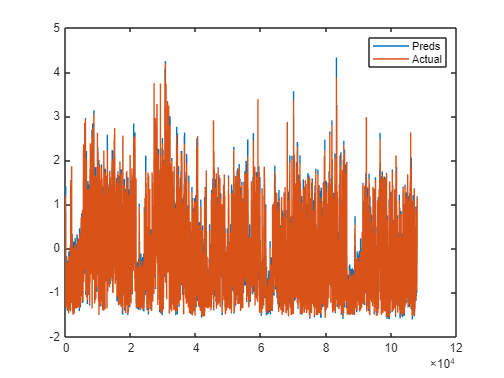

figure, plot(predictTest(:,1))
hold on
plot(actualTest(:,1))
legend({'Preds', 'Actual'})

Compute the root mean squared error (RMSE) of the model prediction for the training and testing data.

RMSE_Train = sqrt(mean((actualTrain - predictTrain).^2))

RMSE_Train = 1×66 single row vector
    0.1194    0.2211    0.2183    0.2044    0.2641    0.2975    0.2802    0.2585    0.3342    0.3969    0.3715    0.3575    0.3135    0.3352    0.3927    0.1236    0.2352    0.2219    0.2133    0.2467    0.3567    0.3183    0.3630    0.3470    0.4001    0.4350    0.4406    0.3566    0.3645    0.3559    0.4761    0.5892    0.3723    0.4182    0.5338    0.4946    0.5707    0.6121    0.6751    0.6424    0.3495    0.4778    0.4845    0.4154    0.4529    0.5617    0.5386    0.5704    0.6823    0.5751


RMSE_Test = sqrt(mean((actualTest - predictTest).^2))

RMSE_Test = 1×66 single row vector
    0.1205    0.2220    0.2403    0.2090    0.2532    0.2952    0.2684    0.2851    0.3526    0.3979    0.3796    0.3653    0.3287    0.3525    0.3965    0.1255    0.2450    0.2552    0.2268    0.2517    0.3698    0.3522    0.3840    0.3641    0.4169    0.4413    0.4714    0.3785    0.3854    0.3787    0.4780    0.5770    0.3068    0.3758    0.4936    0.4649    0.5485    0.6082    0.6074    0.6191    0.4163    0.4140    0.4346    0.3522    0.3720    0.4917    0.4653    0.4432    0.4966    0.4638


Compute the percentage RMSE based on the average for training and test data

% percent_RMSE_Train = RMSE_Train ./ abs(mean(actualTrain))
% percent_RMSE_Test = RMSE_Test ./ abs(mean(actualTest))


Calcutate relatice performance

% Calculate relative difference from training RMSE
relative_performance = (RMSE_Train - RMSE_Test) / RMSE_Train * 100

relative_performance = single
7.1529

% This gives you percentage deviation from training performance

### Predict on Saline data

Helper functions

function [data, mu, sigma] = standardizeByCol(data)
    [n, ~] = size(data);
    mu = mean(data, 1);
    sigma = std(data, 1);
    data = (data - repmat(mu,n,1)) ./ repmat(sigma,n,1);
end